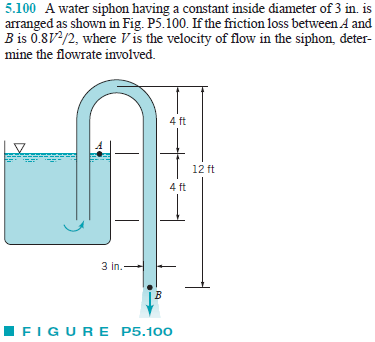

# constants

u = symunit;
gamma = 62.4*u.lbf/u.ft^3;
g = 32.2*u.ft/u.s^2;
rho = 1.94*u.slug/u.ft^3;

# assumptions

old_assum = assumptions;
clearassum;

# inflow properties

% --------------
% given
p1 = 0;
V1 = 0;
z1 = 0;
% --------------

# outflow properties

% --------------
% given
p2 = 0;
V2 = sym('V2', 'positive');
z2 = -(12-4)*u.ft;
D2 = 3*u.in;
% --------------
% area
A2 = sympi*D2^2/4;
% --------------

# conservation of energy

hL(V2) = 0.8*V2^2/(2*g);
V2 = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1-hL);
V2_vpa = vpa(V2, 4) %#ok

$$V2\_vpa = 16.92\,\frac{\mathrm{ft}}{s}$$

Q = rewrite(A2*V2, 'US');
Q_vpa = vpa(Q, 2) %#ok

$$Q\_vpa = 0.83\,\frac{{\mathrm{ft}}^{3}}{s}$$

clear V2_vpa Q_vpa;
setassum(old_assum);